Matlab project :)

**Specific requirements:**

- Introduce the source, format, and background of the data set, what kind of statistical/machine learning task(s) it is originally created for, and websites, papers, or competitions that use the data set.

- Report summary information of the data set, such as #instances, #features (categorical, or numerical), % missing values (if any).

- Visualization of single or small subsets of variables. 

                - Visualization based on 1 - 3 variables at a time should still be performed:

                        - Single categorical variable(s)

                        - General numerical data 

                        - Selected single numerical variables

                        - Selected pairs of variables (both numerical, one numerical + one categorical)

                        - Selected triples of variables (all numerical, two numerical + one categorical)

                        - (if we add reviews) Documents data (refer to data_plotting4.m)

- Feature scaling (if the magnitudes of the variables are very different, normalize them to a common range such as [0,1], or [-1,1])

- Dimension reduction methods to be applied to the data set (for simultaneous visualization of all the numerical variables):  

- Linear, unsupervised: PCA

- Linear, supervised: LDA

- Nonlinear, unsupervised, global: MDS (with any metric except Euclidean) 

- Nonlinear, unsupervised, local: Laplacian Eigenmaps, or another nonlinear one (such as LLE). In the latter case, you must provide a brief, clear description of the algorithm regarding how it works.

Project Steps:

- clean the data

- summary statistics, and visualization of single or small subsets of variables. 

- put all numerical data in a matrix and perform feature scaling

- dimension reduction methods

## **Loading the Data**

clear;
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["App", "Category", "Rating", "Reviews", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "LastUpdated", "CurrentVer", "AndroidVer"];
opts.VariableTypes = ["string", "categorical", "double", "double", "string", "string", "categorical", "string", "categorical", "categorical", "datetime", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["App", "Size", "Installs", "Price", "CurrentVer", "AndroidVer"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["App", "Category", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "CurrentVer", "AndroidVer"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "LastUpdated", "InputFormat", "MMMM d, yyyy");
opts = setvaropts(opts, ["Rating", "Reviews"], "ThousandsSeparator", ",");

% Import the data
data = readtable("data/googleplaystore_v2.csv", opts);
clear opts % clear temporary variables

## **Cleaning the data**

Removing Missing Variables

size(data) % 13 vairables, 10841 apps

ans =        10358          13


Missing data by variable

app = sum(ismissing(data.App));
category = sum(ismissing(data.Category));
rating = sum(ismissing(data.Rating));
reviews = sum(ismissing(data.Reviews));
Size = sum(ismissing(data.Size));
installs = sum(ismissing(data.Installs));
type = sum(ismissing(data.Type));
price = sum(ismissing(data.Price));
contentRating = sum(ismissing(data.ContentRating));
genres = sum(ismissing(data.Genres));
lastUpdated = sum(ismissing(data.LastUpdated));
currentVer = sum(ismissing(data.CurrentVer));
androidVer = sum(ismissing(data.AndroidVer));
table(app, category, rating, reviews, Size, installs, type, price, ...
    contentRating, genres, lastUpdated, currentVer, androidVer)

ans = 1×13 table
    app    category    rating    reviews    Size    installs    type    price    contentRating    genres    lastUpdated    currentVer    androidVer
    ___    ________    ______    _______    ____    ________    ____    _____    _____________    ______    ___________    __________    __________

     0        0         1465        1        0         0         1        0            1            0            1             0             0     


clear Size installs price app rating category reviews type contentRating genres lastUpdated currentVer androidVer;
data( any(ismissing(data),2), :) = [];
data(find(string(data.Size)=='Varies with device'),:) = []; % removing weird size
size(data) % size after deleting a ton of variables.

ans =         7424          13


Fixing data types and removing special characters

% data.Sizes
charSize = strtrim(data.Size);
msize = charSize(endsWith(charSize,'M'));
charSize_m = cellstr(string(str2double(string(strrep(msize,'M', '')))*1000));
charSize(endsWith(charSize,'M')) = charSize_m;
SizeOnlyk = strrep(charSize,'k', '');
data.Size_K = SizeOnlyk;
data.Size_K = str2double(string(data.Size_K));

% data.Installs
data.Installs = str2double(strrep(data.Installs,'+',''));

% data.Price
data.Price = str2double(strrep(data.Price,'$',''));

% cleaning up
clear charSize charSize_m msize SizeOnlyk;

Visualization plan

Summary statistics: (top 5 we create plots for)

- maximum price (top 5)

- average price of paid games

- maximum installs (top 5)

- average installs

- average size

- average rating

- top 5 ratings

- average reviews

- top 5 reviews

single categorical variable: (tien) + summary statistics

- category

- type

- content rating

- genre

single numerical variables: (shayna) + summary statistics

- rating

- reviews

- size

- price

- installs

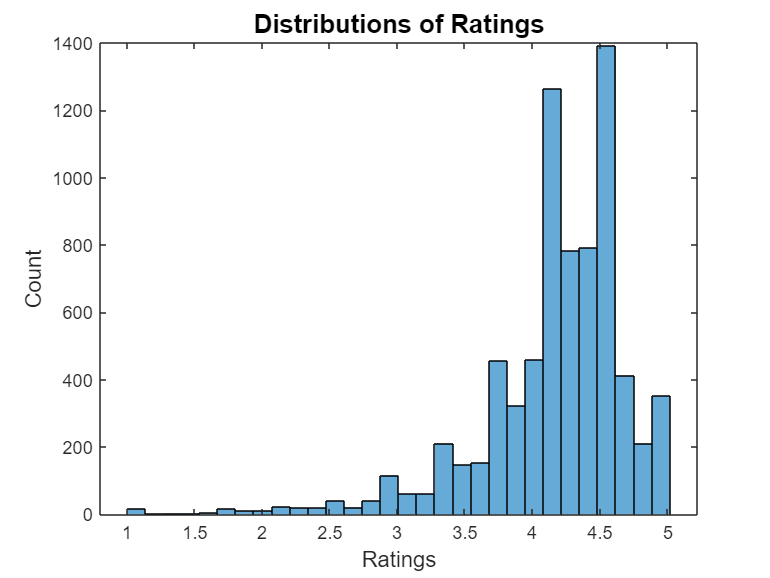

% Ratings plot
histogram(data.Rating,30)
title("Distributions of Ratings",FontSize=14)
xlabel("Ratings",FontSize=12)
ylabel("Count",FontSize=12)

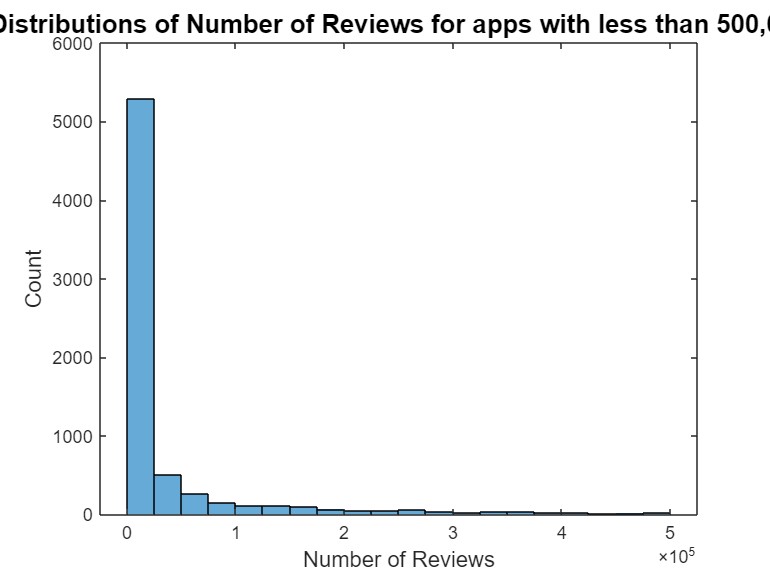

% Reviews plot probably not going to include
histogram(data.Reviews(find(data.Reviews<500000)),20)
title("Distributions of Number of Reviews for apps with less than 500,000",FontSize=14)
xlabel("Number of Reviews",FontSize=12)
ylabel("Count",FontSize=12)

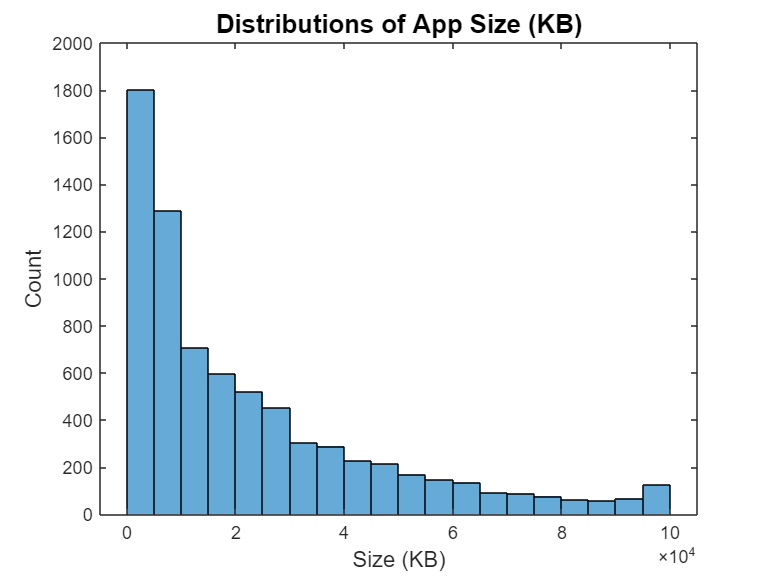

% Size plot
histogram(data.Size_K,20)
title("Distributions of App Size (KB)",FontSize=14)
xlabel("Size (KB)",FontSize=12)
ylabel("Count",FontSize=12)

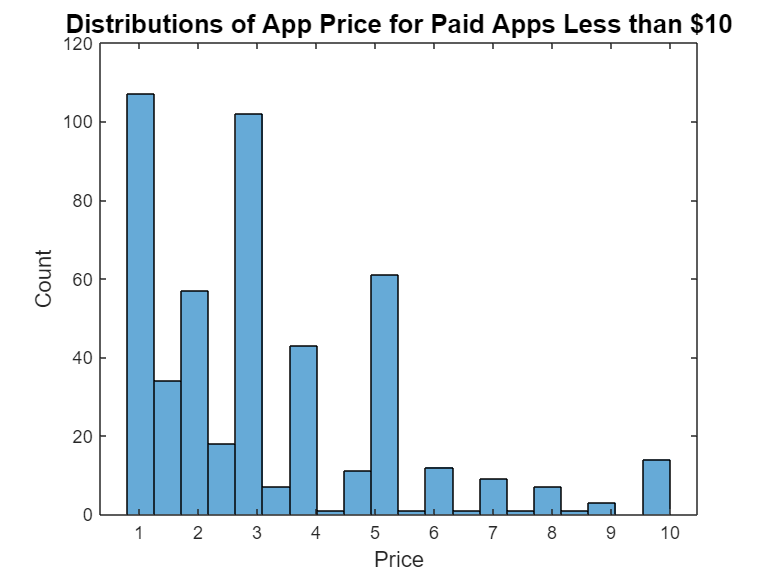

% Price plot
histogram(data.Price(find(data.Price < 10 & data.Price > 0)),20)
title("Distributions of App Price for Paid Apps Less than $10",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Count",FontSize=12)

% Most frequent prices
[n,bin] = hist(data.Price,unique(data.Price));
[~,idx] = sort(-n);
n(idx) % The counts

ans =         6877         104          98          61          53          42          28          16          14          12          11           9           8           8           7           6           4           4           3           3           2           2           2           2           2           2           2           2           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1


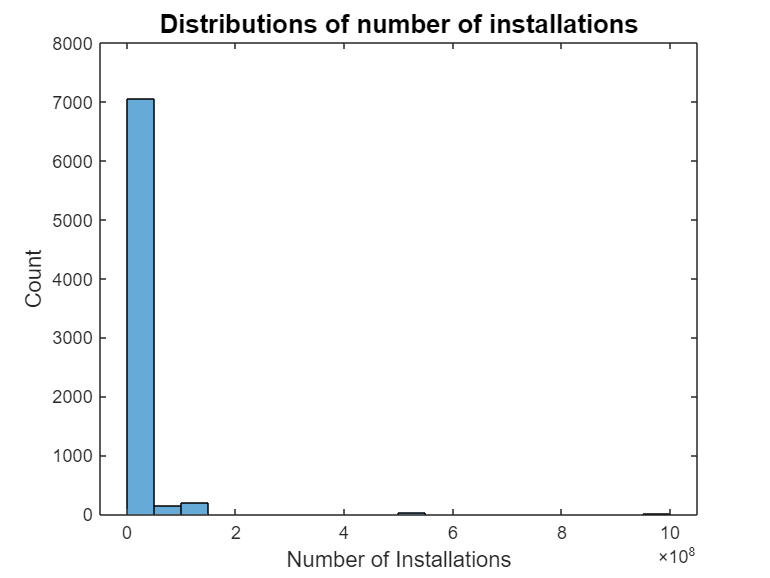


bin(idx); % the prices

% installs plot also terrible
histogram(data.Installs,20) % trying different things
title("Distributions of number of installations",FontSize=14)
xlabel("Number of Installations",FontSize=12)
ylabel("Count",FontSize=12)

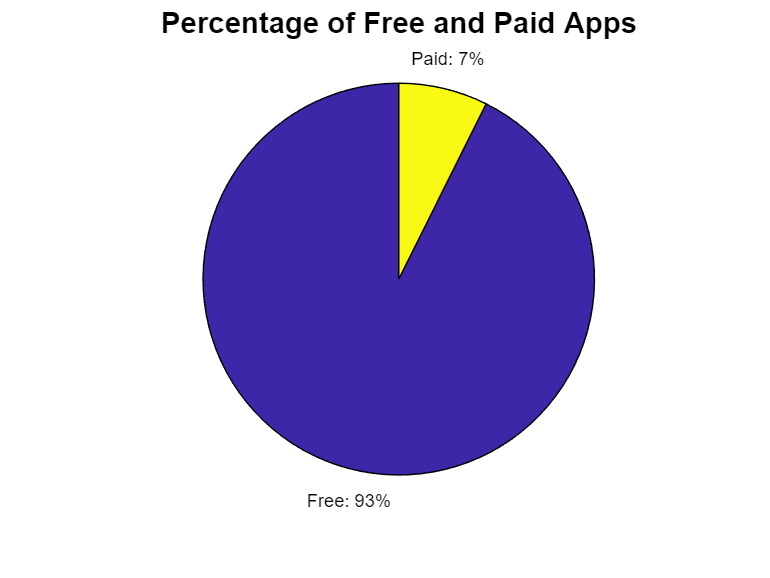


G1 = groupcounts(data,'Type');
p = pie(G1.Percent);
pText = findobj(p,'Type','text');
percentValues = get(pText,'String'); 
txt = {'Free: ', 'Paid: '};
combinedtxt = strcat(txt,percentValues'); 
pText(1).String = combinedtxt(1);
pText(2).String = combinedtxt(2);
title('Percentage of Free and Paid Apps', 'fontsize',16);

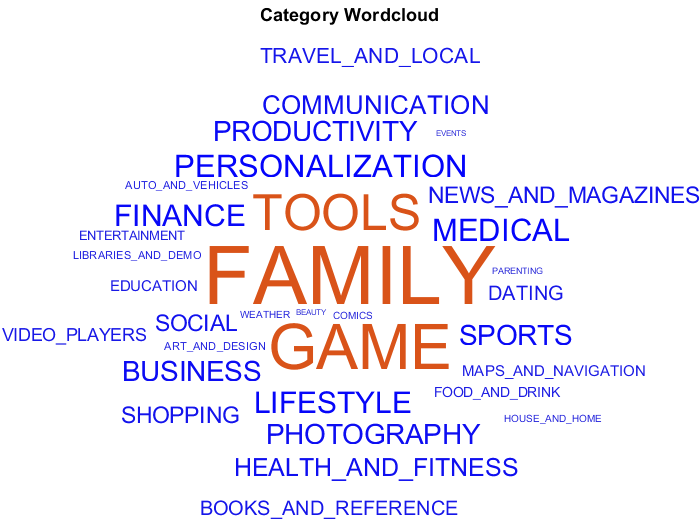

wordcloud(data.Category,'Color','blue');
title('Category Wordcloud')

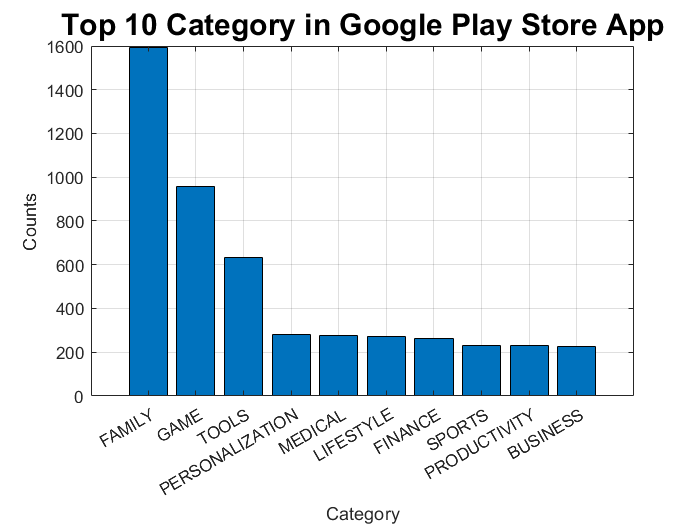

Category = categories(data.Category);
Count = countcats(data.Category);
category_table = table(Category,Count);
category_table = sortrows(category_table,'Count','descend');
top10_category = category_table(1:10,:);
figure
b = bar(top10_category .Count);
xticklabels(top10_category .Category);
ylabel('Counts')
xlabel('Category')
grid on
title('Top 10 Category in Google Play Store App', 'fontsize', 18)

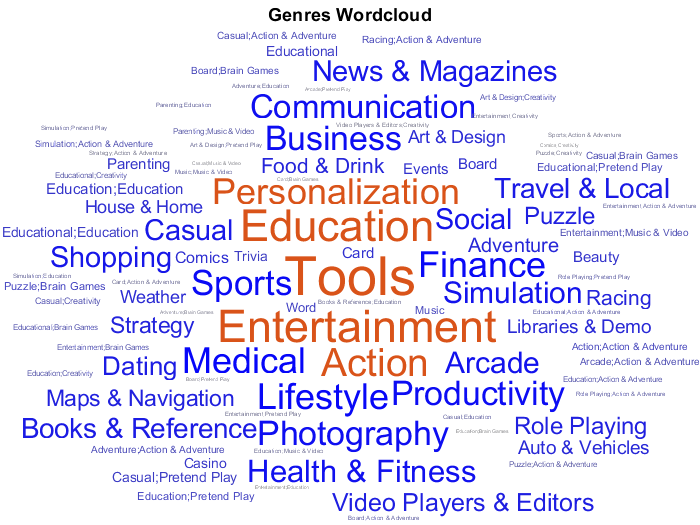

wordcloud(data.Genres,'Color','blue');
title('Genres Wordcloud')

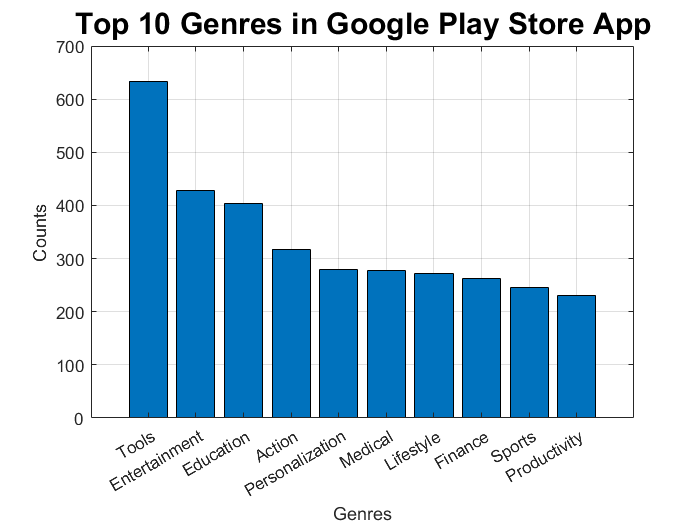

Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top10_genres = genres_table(1:10,:);
figure
b = bar(top10_genres.Count);
xticklabels(top10_genres.Genres);
ylabel('Counts')
xlabel('Genres')
grid on
title('Top 10 Genres in Google Play Store App', 'fontsize', 18)

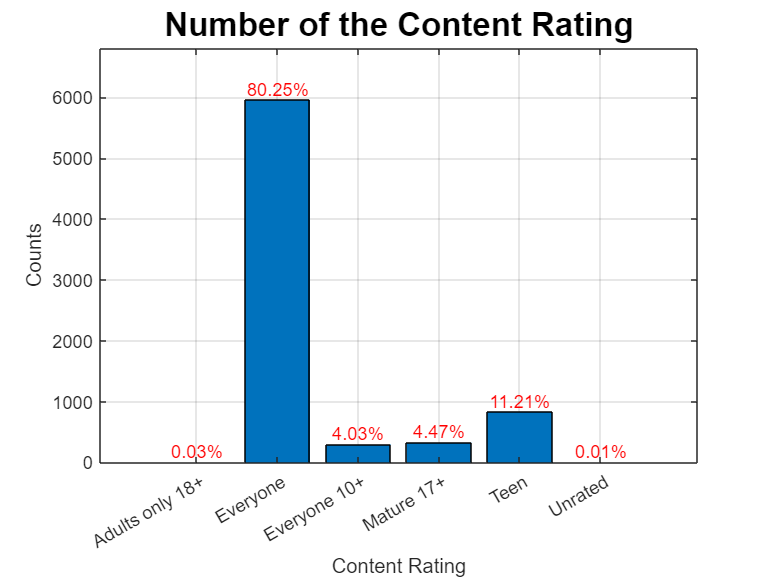

big_category_count = countcats(data.ContentRating);
category_name = categories(data.ContentRating);
conten_Rating_count = groupcounts(data,'ContentRating');
figure
b = bar(big_category_count);
xticklabels(category_name);
ylabel('Counts')
ylim([0 6800])
xlabel('Content Rating')
grid on
title('Number of the Content Rating', 'fontsize', 18)
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(conten_Rating_count.Percent,2)) + '%';
text(xtips,ytips,labels,'Color','red','fontsize',10,'HorizontalAlignment','center','VerticalAlignment','bottom')

#### **Selected pairs of variables both numerical**

- rating

- reviews

- size

- price

- installs

install = data.Installs/1000000000;
review = data.Reviews/1000000;
size = data.Size_K/1000;

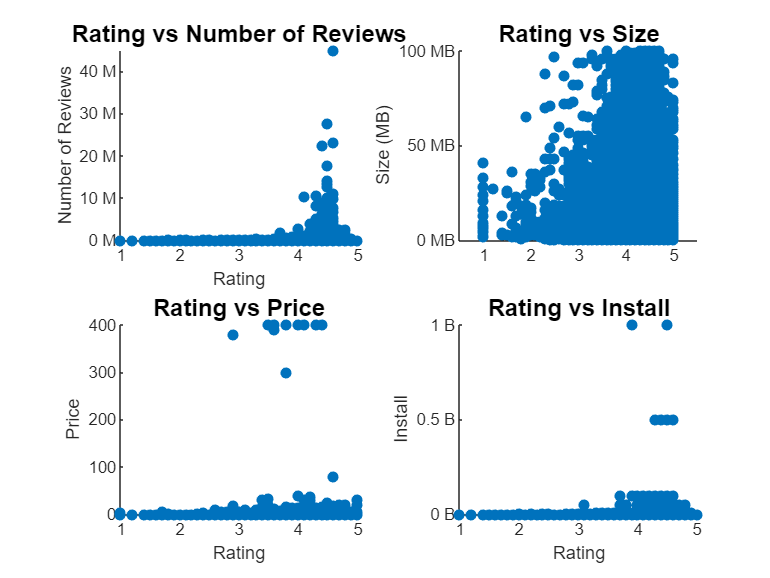

figure;
subplot(2,2,1)
scatter(data.Rating,review,'filled');
ytickformat('%g M')
xlabel('Rating')
ylabel('Number of Reviews')
title('Rating vs Number of Reviews','fontsize', 13)

subplot(2,2,2)
scatter(data.Rating,size,'filled');
title('Rating vs Size','fontsize', 13);
ylabel("Size (MB)")
ytickformat('%g MB')
xlim([0.5 5.5]);

subplot(2,2,3)
scatter(data,"Rating","Price",'filled');
xlabel('Rating')
ylabel('Price')
title('Rating vs Price','fontsize', 13);

subplot(2,2,4)
scatter(data.Rating,install,'filled');
ytickformat('%g B')
xlabel('Rating')
ylabel('Install')
title('Rating vs Install','fontsize', 13);

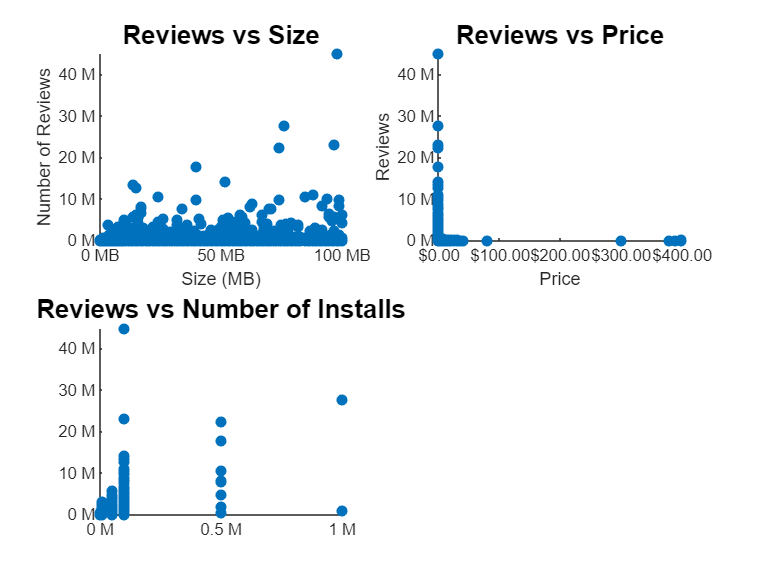

figure;
subplot(2,2,1)
scatter(size,review,'filled');
title('Reviews vs Size','fontsize', 14);
xlabel("Size (MB)")
xtickformat('%g MB')
ytickformat('%g M')
ylabel('Number of Reviews')

subplot(2,2,2)
scatter(data.Price,review,'filled');
xlabel('Price')
xtickformat('usd')
ytickformat('%g M')
ylabel('Reviews')

title('Reviews vs Price','fontsize', 14);

subplot(2,2,3)
scatter(install,review,'filled');
title('Reviews vs Number of Installs','fontsize', 14);
xtickformat('%g M')
ytickformat('%g M')

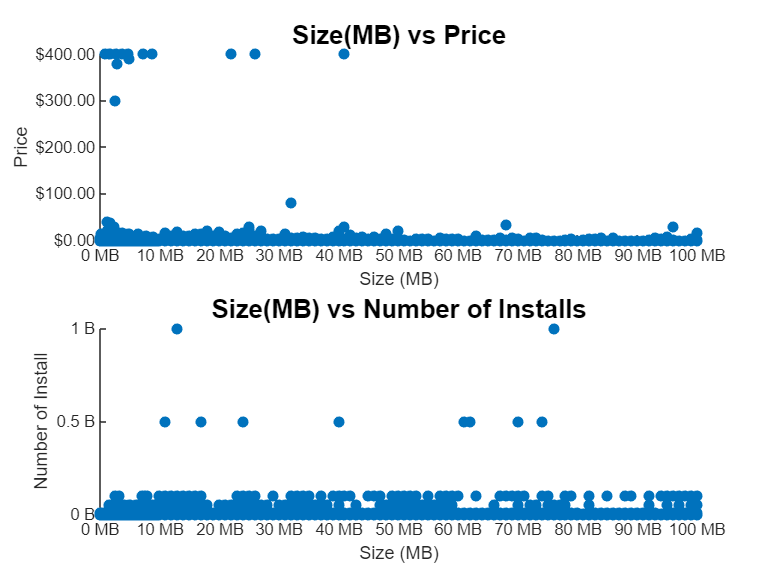

figure;
subplot(2,1,1);
scatter(size,data.Price,'filled');
xlabel('Size (MB)');
xtickformat('%g MB');
ylabel('Price');
ytickformat('usd');
title('Size(MB) vs Price','fontsize', 14);
subplot(2,1,2)
scatter(size,install,'filled');
xlabel('Size (MB)')
xtickformat('%g MB')
ylabel('Number of Install')
ytickformat('%g B')
title('Size(MB) vs Number of Installs','fontsize', 14);

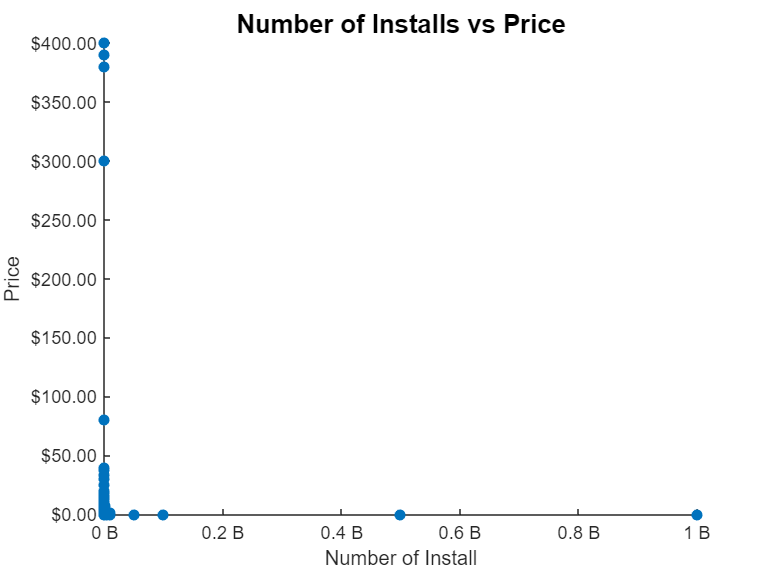

figure;
scatter(install,data.Price,'filled');
xlabel('Number of Install')
xtickformat('%g B')
ylabel('Price')
ytickformat('usd')
title('Number of Installs vs Price','fontsize', 14);

Selected pairs of variables one numerical + one categorical (shayna)

Selected triples of variables all numerical (tien)

Selected triples of variables two numerical + one categorical (shayna)